clear 



miniscope_analysis_NG

filepath = '/Users/mkindel/Documents/MSanalysis_temp/2023_04_25_mk234_ss3_HIIT_cut_mat'



maxframes = 3685

maxframes = 3685


%can comment lines 8 and 9 out if you arent interested in taking the means
%from different time points 
exercise_start = 1000

exercise_start = 1000

exercise_end = 1500

exercise_end = 1500

K = 3 %number of clusters, determined visually via bento but better ways to do this

K = 3

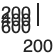

K_Tz = kmeans(Tz,K,'replicates',10);
K_Tz_combined = [K_Tz, Tz]; 

%visualizes max projection of cells 
imagesc(proj)


% saveas(gcf,fullfile(filepath,'maxProj.png'))
% saveas(gcf,fullfile(filepath,'maxProj.svg'))

numCells = length(Tz(:,1));
numFrames = length(Tz(1,:));
type1 = []; %pretty sure this is unnessecary  
% 

%creates a type 1 cell variable 

c1= 0; 
for i = 1:numCells
   
    if K_Tz_combined(i, 1) == 1
       c1= c1+1;
       type1(c1,:) = [Tz(i,:)];
    end 
    
end
type1( all(~type1,2), : ) = []; %removes rows of 0 for some unknown reason

%creates a type 2 cell variable 
c2= 0; 
for i = 1:numCells
   
    if K_Tz_combined(i, 1) == 2
       c2= c2+1;
       type2(c2,:) = [Tz(i,:)];
    end 
    
end
type2( all(~type2,2), : ) = []; %removes rows of 0

%creates a type 3 cell variable 

c3= 0; 
for i = 1:numCells
   
    if K_Tz_combined(i, 1) == 3
       c3= c3+1;
       type3(c3,:) = [Tz(i,:)];
    end 
    
end
type3( all(~type3,2), : ) = []; %removes rows of 0


%finds means for each cluster. Can plot each to visualize the average trace
meanType1 = mean(type1);
meanType2= mean(type2);
meanType3 = mean(type3);

combinedTypeMeans = [meanType1;meanType2;meanType3];

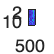

% % unnessecary 
% find max peak 
% clear E index sorted1
% for i = 1:length(type1(:,1)) 
%     type1_indMax (i,:) = max(type1(i,1:exercise_start));
%     type1_indMax_real(i,1) = mean(type1_indMax(i,:));
% end
% 
% sorted1 = [type1_indMax_real,type1];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear E index sorted1 imagesc(E)


% %% % unnessecary 
% find max peak 
% clear E index sorted1
% for i = 1:length(type2(:,1)) 
%     type2_indMax (i,:) = max(type2(i,1:exercise_start));
%     type2_indMax_real(i,1) = mean(type2_indMax(i,:));
% end
% 
% sorted1 = [type2_indMax_real,type2];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN

E =        NaN   -1.6270   -1.6270   -1.6270   -1.6270   -1.6270   -1.6270   -1.6270   -1.6270   -1.6270   -1.5783   -1.4882   -1.4018   -1.3190   -1.2403   -1.1656   -1.0951   -1.0289   -0.9670   -0.9096   -0.8564   -0.8076   -0.7631   -0.7228   -0.6866   -0.6543   -0.6259   -0.6011   -0.5799   -0.5620   -0.5588   -0.5636   -0.5683   -0.5731   -0.5778   -0.5825   -0.5872   -0.5918   -0.5964   -0.6010   -0.6056   -0.6102   -0.6148   -0.6193   -0.6238   -0.6283   -0.6327   -0.6372   -0.6416   -0.6460
       NaN   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0.8805   -0

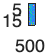

% 
% imagesc(E)

% clear E index sorted1
% 


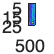

% % unnessecary 
%find max peak 
% clear E index sorted1
% for i = 1:length(type3(:,1)) 
%     type3_indMax (i,:) = max(type3(i,1:exercise_start));
%     type3_indMax_real(i,1) = mean(type3_indMax(i,:));
% end
% 
% sorted1 = [type3_indMax_real,type3];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear E index sorted1



    
%  for i = 1:length(type1(:,1)) 
% %     type1_pre(i,:) = (type1(i,1:exercise_start));
% %     mean_type1_pre(i,1) = mean(type1_pre(i,:));
% % end 
% maxType1 = max(meanType1)
% maxType2= max(meanType2)
% maxType3 = max(type3);
% combinedTypeMax = [maxType1;maxType2];


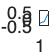

%only need if you want to find means for different time points, otherwise
%can comment out 
%split type 1 by pre, ex, post 

%pre
for i = 1:length(type1(:,1))
    type1_pre(i,:) = (type1(i,1:exercise_start));
    mean_type1_pre(i,1) = mean(type1_pre(i,:));
end 

%ex
for i = 1:length(type1(:,1)) 
    type1_ex(i,:) = (type1(i,exercise_start+1:exercise_end));
    mean_type1_ex(i,1) = mean(type1_ex(i,:));
end 

%post
for i = 1:length(type1(:,1)) 
    type1_post(i,:) = (type1(i,exercise_end+1:end));
    mean_type1_post(i,1) = mean(type1_post(i,:));
end 
combinedtype1 = [mean_type1_pre, mean_type1_ex, mean_type1_post];
plot(mean(combinedtype1)) %not well labeled but plots mean signal pre, during and post exercise for single cell type

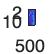

%sorts one cell type at one time point by mean activity
%kind of useless, i just like looking at it
% sorted1 = [mean_type1_post,type1];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear sorted1 E index imagesc(E)

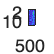

%sorts one cell type at one time point by mean activity
% sorted1 = [mean_type1_ex,type1];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear sorted1 E index imagesc(E)

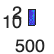

%sorts one cell type at one time point by mean activity
% sorted1 = [mean_type1_pre,type1];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear sorted1 E index

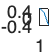

%split type 2 by pre, ex, post 
%only need if you want to find means for different time points, otherwise
%can comment out 
for i = 1:length(type2(:,1)) 
    type2_pre(i,:) = (type2(i,1:exercise_start));
    mean_type2_pre(i,1) = mean(type2_pre(i,:));
end 

%ex
for i = 1:length(type2(:,1)) 
    type2_ex(i,:) = (type2(i,exercise_start+1:exercise_end));
     mean_type2_ex(i,1) = mean(type2_ex(i,:));
end 


%post
for i = 1:length(type2(:,1)) 
    type2_post(i,:) = (type2(i,exercise_end+1:end));
    mean_type2_post(i,1) = mean(type2_post(i,:));
end 
combinedtype2 = [mean_type2_pre, mean_type2_ex, mean_type2_post];
plot(mean(combinedtype2)) 


% 

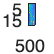

%sorts one cell type at one time point by mean activity
% sorted1 = [mean_type2_post,type2];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear imagesc(E) sorted1 E index imagesc(E)

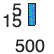

%sorts one cell type at one time point by mean activity
% sorted1 = [mean_type2_ex,type2];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear sorted1 E index 

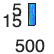

%sorts one cell type at one time point by mean activity
% sorted1 = [mean_type2_pre,type2];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear sorted1 E index

%split type 3 by pre, ex, post 
%only need if you want to find means for different time points, otherwise
%can comment out 
for i = 1:length(type3(:,1)) 
    type3_pre(i,:) = (type3(i,1:exercise_start));
     mean_type3_pre(i,1) = mean(type3_pre(i,:));
end 

%ex
for i = 1:length(type3(:,1)) 
    type3_ex(i,:) = (type3(i,exercise_start+1:exercise_end));
    mean_type3_ex(i,1) = mean(type3_ex(i,:));
end 

%post
for i = 1:length(type3(:,1)) 
    type3_post(i,:) = (type3(i,exercise_end+1:end));
    mean_type3_post(i,1) = mean(type3_post(i,:));
end 
combinedtype3 = [mean_type3_pre, mean_type3_ex, mean_type3_post]

combinedtype3 =    -0.9561   -0.3226    0.7596
   -1.2764    0.2633    0.7782
   -1.0024    0.2986    0.5800
   -0.3429    0.9632   -0.0943
   -0.8650    0.5039    0.4167
   -0.9431   -0.4496    0.7940
   -0.9878    0.0305    0.6612
    0.2375   -0.3211   -0.0523
   -0.9646    0.1182    0.6155
   -0.9053   -0.3107    0.7210


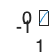

plot(mean(combinedtype3))

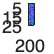

%sorts one cell type at one time point by max activity, 
% %find max peak 
% clear E index sorted1
% for i = 1:length(type3_post(:,1)) 
%     type3_indMax (i,:) = max(type3_post(i,1:exercise_start));
%     type3_indMax_real(i,1) = mean(type3_indMax(i,:));
% end
% 
% sorted1 = [type3_indMax_real,type3_post];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear E index sorted1

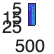


% sorted1 = [mean_type3_post,type3];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear sorted1 E index

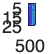

% sorted1 = [mean_type3_ex,type3];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear sorted1 E index

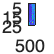

% sorted1 = [mean_type3_pre,type3];
% [E,index] = sortrows(sorted1,1,'ascend');
% E(:,1) = NaN;
% imagesc(E)

% clear sorted1 E index

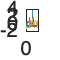

%plots mean signal for each cell type, overlayed
plot(meanType1, 'LineWidth',0.75)
hold on 
plot(meanType2,'LineWidth',0.75)
hold on 
plot(meanType3,'LineWidth',0.75)


hold off


%comment out below 2 lines if you dont care about saving the figs 
saveas(gcf,fullfile(filepath,'meanTypes_overlayed.png'))

Error using print
Functionality not supported with figures created with the uifigure function.

Error in saveas (line 181)
        print( h, name, ['-d' dev{i}] )

saveas(gcf,fullfile(filepath,'meanTypes_overlayed.svg'))
% 

% %smoothed
% 
% smoothMeanType1 = smoothdata(meanType1,"movmean",50);
% smoothMeanType2 = smoothdata(meanType2,"movmean",50);
% smoothMeanType3 = smoothdata(meanType3,"movmean",200);
% 
% plot(smoothMeanType1, 'LineWidth',1.5)
% hold on 
% plot(smoothMeanType2,'LineWidth',1.5)
% hold on 
% plot(smoothMeanType3,'LineWidth',1.5)
% hold off



% %plots mean signal from each cell type, (poorly) seperated 
% combinedTypeMeans = [meanType1; meanType2; meanType3]
% [m n] = size(combinedTypeMeans);
% sizeAdd = 2;
% for i = 1:m
%     newTplot(i,:) = combinedTypeMeans(i,:)+(i*sizeAdd);
% end
% 
% plot(F, newTplot,'LineWidth',0.75)
% % annotation("line", [0.3155 0.3155], [0.109 0.9280])
% % annotation("line", [0.593 0.593], [0.109 0.9280])


%plot individual traces from type 1
[m n] = size(type1);
sizeAdd = 5;
for i = 1:m
    stacked_type1(i,:) = type1(i,:)+(i*sizeAdd);
end
plot(F, stacked_type1,'LineWidth',1)
xlabel("Frames")
xticks([0:5000:25000])

%comment out below two lines if you dont care about saving 
saveas(gcf,fullfile(filepath,'type1_indtraces.png'))
saveas(gcf,fullfile(filepath,'type1_indtraces.svg'))


%plot individual traces from type 2
[m n] = size(type2);
sizeAdd = 5;
for i = 1:m
    stacked_type2(i,:) = type2(i,:)+(i*sizeAdd);
end
plot(F, stacked_type2,'LineWidth',1)
xlabel("Frames")
xticks([0:5000:25000])

%comment out below two lines if you dont care about saving 
saveas(gcf,fullfile(filepath,'type2_indtraces.png'))
saveas(gcf,fullfile(filepath,'type2_indtraces.svg'))


%plot individual traces from type 3
[m n] = size(type3);
sizeAdd = 5;
for i = 1:m
    stacked_type3(i,:) = type3(i,:)+(i*sizeAdd);
end
plot(F, stacked_type3,'LineWidth',1)
xlabel("Frames")
xticks([0:5000:25000])

%comment out below two lines if you dont care about saving 
saveas(gcf,fullfile(filepath,'type3_indtraces.png'))
saveas(gcf,fullfile(filepath,'type3_indtraces.svg'))



% i dont remember what this is 
% [m n] = size(type1);
% sizeAdd = 6;
% for i = 1:m
%     stacked_type1(i,:) = type1(i,:)+(i*sizeAdd);
% end
% plot(F, stacked_type1,'LineWidth',1)
% hold on 
% 
% [m n] = size(type2);
% for i = 1:m
%     stacked_type2(i,:) = type2(i,:)+(i*sizeAdd);
% end
% plot(F, stacked_type2,'LineWidth',0.75)
% hold on 
% 
% [m n] = size(type3);
% for i = 1:m
%     stacked_type3(i,:) = type3(i,:)+(i*sizeAdd);
% end
% plot(F, stacked_type3,'LineWidth',0.75)
% hold off


fig_meanType1 = plot(F, meanType1)  



fig_meanType2 = plot (F, meanType2)


fig_meanType3 = plot (F, meanType3)

% colormap jet(15);
% 
% 
%HMtype1 = imagesc(type1)

% 
% 
% 
% colormap jet(15);
% 
%HMtype2 = imagesc(type2)
% 

savefiles = input("do you want to save (y/n)?", "s")
if savefiles == 'y'
    save(fullfile(filepath, "matlab_output_3clusters.mat"), "type1", "type2", "type3", "Tz","TzRaw", "-mat")
end

